clear all; clc;

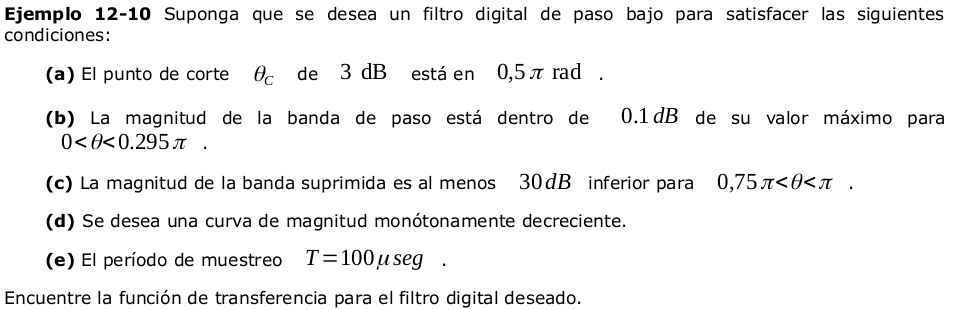

**Datos condiciones de un filtro digital**

theta_c=0.5*pi;
A1=0.1; %db
theta_1=0.295*pi;
A2=30; %db
theta_2=0.75*pi;
T=sym(100*1E-6);

Traduciendo los criterios digitales a criterios analógicos.

w: frecuencia analógica.

fprintf('Traduciendo los criterios digitales a criterios analógicos');

Traduciendo los criterios digitales a criterios analógicos

wc=2/T*tan(theta_c/2);
w1=2/T*tan(theta_1/2);
w2=2/T*tan(theta_2/2);
fprintf('Frecuencia de corte desnormalizadas: wc=%.2f',wc);

Frecuencia de corte desnormalizadas: wc=20000.00

fprintf('Frecuencia en banda de paso: w1=%.2f',w1);

Frecuencia en banda de paso: w1=9993.40

fprintf('Frecuencia en banda suprimida: w2=%.2f',w2);

Frecuencia en banda suprimida: w2=48284.00

**Función de aproximación butterworth**

syms w 'real', syms n 'integer'
H2(w)=1/(1 + (w/wc)^(2*n))

$$H2(w) = \frac{1}{{\left(5.0000e-05\,w\right)}^{2\,n}+1}$$

**Condiciones requeridas.**

n1=vpasolve(-10*log10(H2(w1))==A1, n);
n2=vpasolve(-10*log10(H2(w2))==A2, n);
nb=n1;
if nb<n2
  nb=n2;
end
fprintf('Orden de: cond1->%d, cond2->%d, elegido->%d',n1,n2,nb);

Orden de: cond1->3, cond2->4, elegido->4

syms s 'real', syms k 'integer';
theta(k)=((2*k-1)/(2*nb))*pi;
H_pb(s,k)=1/(s^2 + 2*sin(theta(k))*s + 1);
H(s)=prod(H_pb(s,sym(1:nb/2)));

if mod(nb,2)~=0
  H(s)=H(s)/(s+1);
end

Función de transferencia

H(s)

$$ans = \frac{1}{\left(s+1\right)\,\left(s^{2}+0.7805\,s+1\right)}$$

Respuesta en frecuencia s

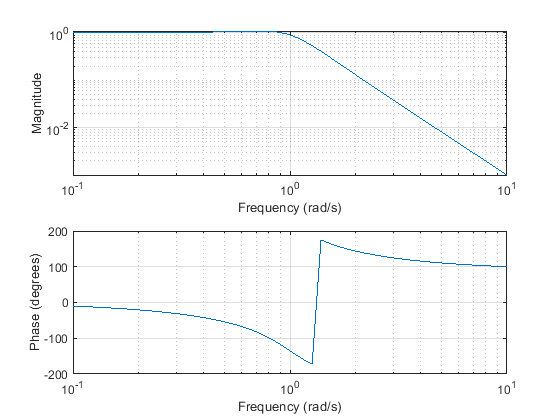

[B,A]=numden(H(s));
b= sym2poly(collect(B));
a= sym2poly(collect(A));
w=logspace(-1,1);
clf, freqs(b,a,w);

**Integración numérica - método de euler**

syms z, syms Ts 'real';

HzT(z)=subs( H(s), s=(2/Ts)*(1-z^-1)/(1+z^-1)) ;
HzT(z)=collect(HzT(z), z^-1 )

$$HzT(z) = \frac{{\mathrm{Ts}}^{3}+\frac{3\,{\mathrm{Ts}}^{3}}{z}+\frac{3\,{\mathrm{Ts}}^{3}}{z^{2}}+\frac{{\mathrm{Ts}}^{3}}{z^{3}}}{7.1220\,\mathrm{Ts}-\frac{-3\,{\mathrm{Ts}}^{3}-3.5610\,{\mathrm{Ts}}^{2}+7.1220\,\mathrm{Ts}+24}{z}-\frac{-3\,{\mathrm{Ts}}^{3}+3.5610\,{\mathrm{Ts}}^{2}+7.1220\,\mathrm{Ts}-24}{z^{2}}+\frac{{\mathrm{Ts}}^{3}-3.5610\,{\mathrm{Ts}}^{2}+7.1220\,\mathrm{Ts}-8}{z^{3}}+3.5610\,{\mathrm{Ts}}^{2}+{\mathrm{Ts}}^{3}+8}$$

Periodo de muestreo;

Hz(z)=subs(HzT(z),Ts=T)

$$Hz(z) = -\frac{\frac{3.0000e-12}{z}+\frac{3.0000e-12}{z^{2}}+\frac{1.0000e-12}{z^{3}}+1.0000e-12}{\frac{24.0007}{z}-\frac{23.9993}{z^{2}}+\frac{7.9993}{z^{3}}-8.0007}$$

**Respuesta en frecuencia**

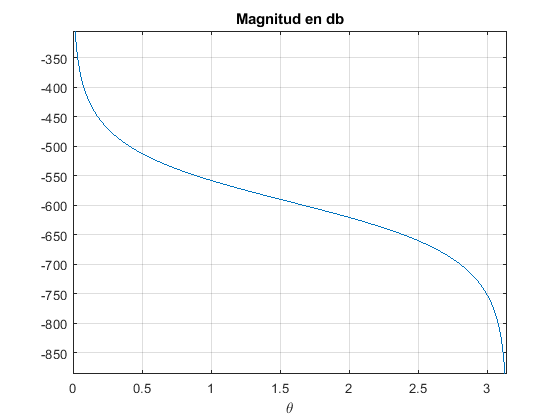

syms theta 'real';
clf; ezplot(20*log(abs( Hz(exp(j*theta)) )),[0,pi]), title('Magnitud en db'); grid on;

**Respuesta en frecuencia**

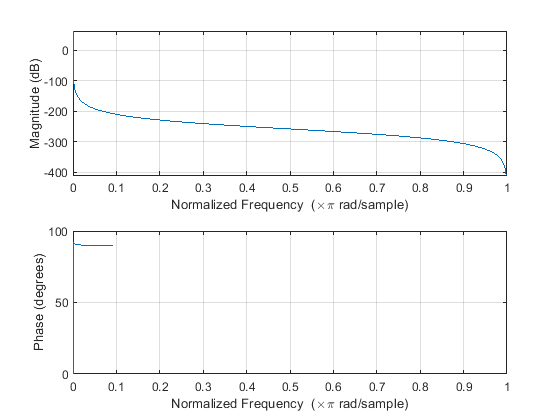

[Bz,Az]=numden(Hz(z));
bz=sym2poly(Bz); az=sym2poly(Az);
clf; freqz(bz, az)

comparativa caso analógico - caso digital

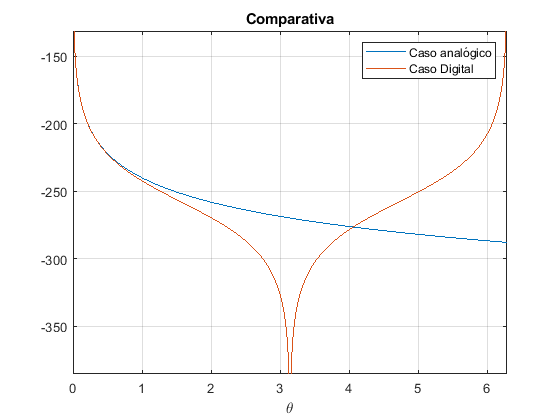

syms wN 'real';
HwN(wN)=subs(H(s), s=j*wN/T );
clf; ezplot(20*log10(abs( HwN(wN) )),[0,2*pi]);
hold on ;

ezplot(20*log10(abs( Hz(exp(j*theta) ))),[0,2*pi]);
legend('Caso analógico', 'Caso Digital' );
title('Comparativa');
hold off; grid on;